# Genetic Algorithm in MATLAB -- Robot Path Planning for 2D Static Environment

## Author: Azmyin Md. Kamal

## Version : 5.0

## Date: 11/15/2020

## Map : 1

## 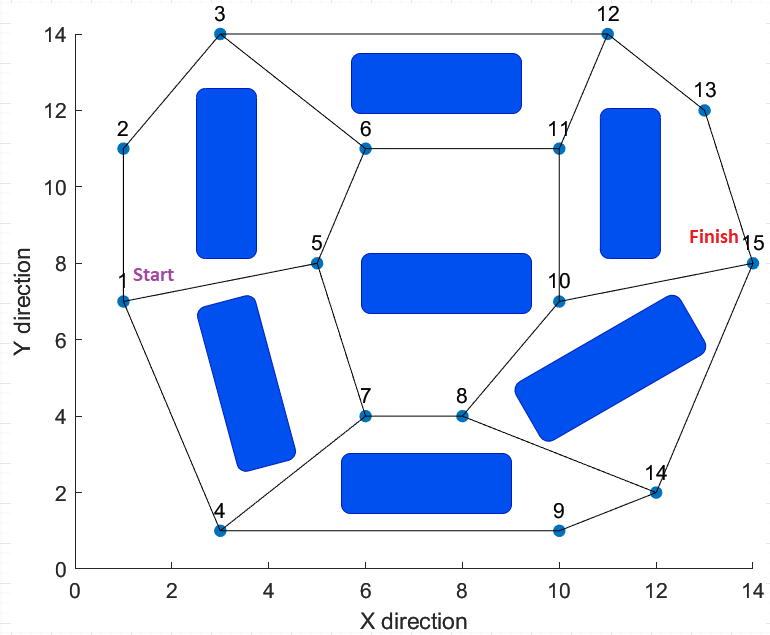

## Features

- In the code, functions with label UNIQUE PROBLEM FUNCTION / HARDCODED are problem specific functions

- True Elitisim -- Copy the most fit individual to next generation

- Bit flip mutation

- 90% crossover

- Multi point cross over operator

- Two new heuristic rules check_minima_rules and inject_global_best. 

- 3 feasible path provided in Generation 1

- Numerical Roullete Wheel Selection - chose with replacement

- Automatic best path plot per generation with fitness value and distance travelled

## Observations:

- Mate pooling with replacement seems to find

- Optimal path reported in [1] is not 100% guranteed to converge in every iteration. This issue was not reported in the paper

- Providing more solution path imporves the overall search. This warrents further investigation to the nature of graph based path-planning

## References

- Map 1 is based on G. Nagib and W. Gharleb (2004), "Path planning for a mobile robot using using genetic algorithm" (http://citeseerx.ist.psu.edu/viewdoc/summary?doi=10.1.1.324.42)

- Adam Danz (2020). labelpoints (https://www.mathworks.com/matlabcentral/fileexchange/46891-labelpoints), MATLAB Central File Exchange. Retrieved November 9, 2020.

- Kamal, Azmyin M. (2020), "Collison-Free, Shortest-Path Planning for Mobile Robots in 2D Static Workspace using Genetic Algorithm" *Manuscript under preparation*

## To-do

- Directed Acyclic Graph to generate feasible solution 

- J. Lee and D.-W. Kim, “An effective initialization method for genetic algorithm-based robot path planning using a directed acyclic graph,”Information Sciences, vol. 332, pp. 1–18, 2016.

## Define Parameters

clc;
clear all;

% HARDCODED, CHANGES WITH MAP OF THE ENVIRONMENT
bit_count = 4; % [4 = paper, 8 = experimental]
m = 7; % Number of static obstacles,
% HARDCODED, CHANGES WITH MAP OF THE ENVIRONMENT

% Provide inputs
N = 10; % Minimum 3
num_iter = 50; % How many generations do we want to make?

% HARDCODED, if you change this, you must provide a new feasible path in
% random_g1.m
s_loc = 1;
e_loc = 15;

% Input, starting location and finishing location
[point_mat, path_index, point_ls] = load_dat(s_loc,e_loc);
% point_ls = [start_point,finish_point,min_point_index,max_point_index];

## Load Seed Generation

% Setup global varialbes
global global_elite_count;
global global_elite_path;
global global_elite_fitness;
global most_fit_candidate;
global current_candidate_fitness;
global_elite_count = 1;
global_elite_path = [];
most_fit_candidate = [];
current_candidate_fitness = 0;
global_elite_fitness = 0;
% Setup global varialbes

% Setup experiment
gen_count = 1;
plot_path = 1;
% random_g1 is modified to insert some possible path.
% Possible path locations are subject to human judgement
[x_current, chromo_len] = random_g1(N,bit_count,m,point_ls(1,1), point_ls(1,2), point_ls(1,3), point_ls(1,4));

%x_current % Debug

## Run Calculations

for i = 1:num_iter
    gen_count = i; % Track current generation number
    if (gen_count > 1)
        seed_tab = 0; % Ensure we are seeing the correct table
    end
    fprintf("---------------------------------------Generation %d -----------------------------------\n",gen_count);
    fprintf("\n")
    x_future = run_genetic_algo(gen_count,bit_count,x_current, N, path_index, point_mat, point_ls,m);
    
    % Draw path figure here
    if (plot_path == 1)
        ff = print_best_path(most_fit_candidate, current_candidate_fitness,gen_count, point_mat, point_ls, path_index);
    end
    
    % Update to go to next generation
    x_current = x_future;
    fprintf("")
    %fprintf("\n---------------------------------------################ -----------------------------------\n");
end